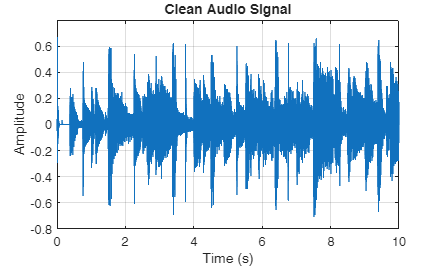

% importing clean audio signal

source_audio = audioread("clean_audio_file.wav");
Fs = audioinfo("clean_audio_file.wav").SampleRate;
ts = 0:(1/Fs):10;
clean_audio = source_audio(1:length(ts));

figure();
plot(ts, clean_audio);
grid on;
xlabel("Time (s)");
ylabel("Amplitude");
title("Clean Audio Signal");

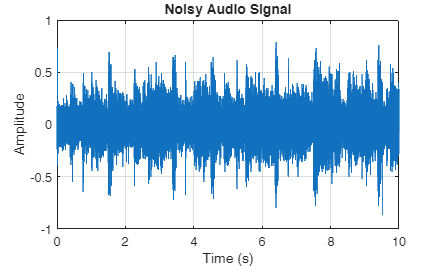

% importing noise signal
noise_audio = audioread("supermarket_noise.wav");
noise_audio = noise_audio(1:min(length(noise_audio), length(clean_audio)));
noise_audio = noise_audio(:)';

% Add noise to the clean signal and visualize the result
noisyAudio = clean_audio + noise_audio;
audiowrite("noisy_audio.wav", noisyAudio, Fs);

figure();
plot(ts(1:length(noisyAudio)), noisyAudio);
grid on;
xlabel("Time (s)");
ylabel("Amplitude");
title("Noisy Audio Signal");

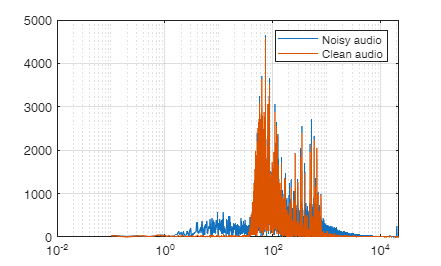


% listen the noisy the signal
sound(noisyAudio, Fs)

% frequency spectrum of both the signals
clean_spectrum = abs(fft(clean_audio));
noisy_spectrum = abs(fft(noisyAudio));
frequency = 0:(Fs/length(ts)):(Fs/2);


figure();
plot(frequency, noisy_spectrum(1:length(frequency)));
hold on;
plot(frequency, clean_spectrum(1:length(frequency)));
hold off;
grid on;
legend("Noisy audio", "Clean audio");
xscale log

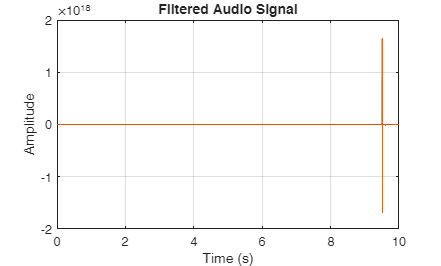

filtered_signal = lms_adaptive_filter_func(noisyAudio, noise_audio, 4e-2);

figure();
plot(ts, noisyAudio, "--");
hold on;
plot(ts, filtered_signal);
hold off;
grid on;
xlabel("Time (s)");
ylabel("Amplitude");
title("Filtered Audio Signal");


% listen to filtered signal
sound(filtered_signal, Fs);

% comparing for different step sizes
stepSizes = [2e-3, 2.4e-3, 2.8e-3, 3e-3];
N = length(ts);
for i = 1:length(stepSizes)
    filtered_signal(i,:) = lms_adaptive_filter_func(noisyAudio, noise_audio, stepSizes(i));
    snratio = snr(clean_audio, filtered_signal(i,:) - clean_audio)
end

snratio = 2.9573

snratio = 3.6018

snratio = 4.1083

snratio = 4.3214

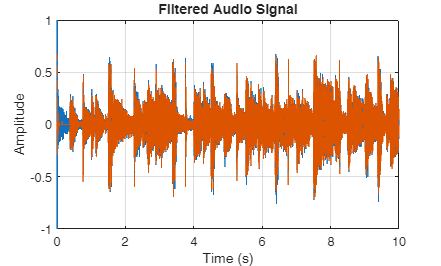

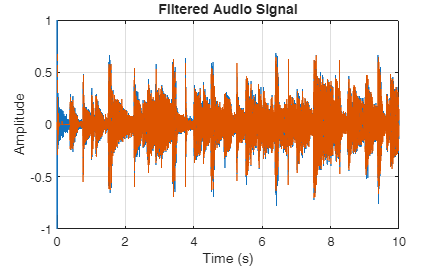

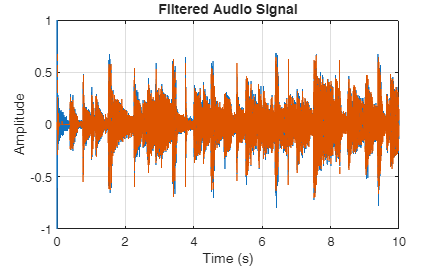

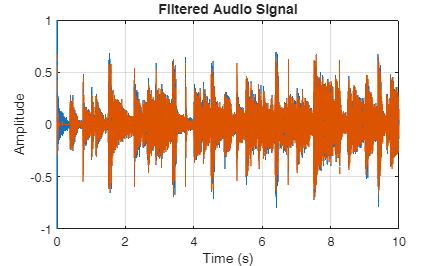



for i = 1:length(stepSizes)
    figure();
    plot(ts, filtered_signal(i, :));
    hold on;
    plot(ts, clean_audio, "--");
    hold off;
    grid on;
    xlabel("Time (s)");
    ylabel("Amplitude");
    title("Filtered Audio Signal");
    ylim([-1, 1])
end


% optimal step size is 2.4e-3

sound(filtered_signal(2,:), Fs)